# Full Data Processing Pipeline

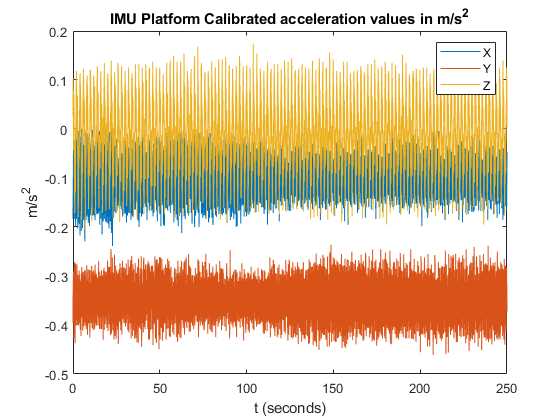

% Author: Michael Noyce
% This data processing pipeline is implemented in the STM32L4
% on the UCT SHARC Buoy, this MATLAB program is the golden measure 
% for the software implementation

% Stage 0: Data Input
% Pre-processing of raw IMU Data
IMUData = readtable('05Hz_20mm_reg.csv');
rawXAcc = IMUData{:, 2}(20000:45000);
rawYAcc = IMUData{:, 3}(20000:45000);
rawZAcc = IMUData{:, 4}(20000:45000);
rawRoll = IMUData{:, 5}(20000:45000);
rawPitch = IMUData{:, 6}(20000:45000);
rawYaw = IMUData{:, 7}(20000:45000);

Fs = 100;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = height(rawXAcc);             % Length of signal
t = (0:N-1)*T;        % Time vector
d_sample_ratio = 20; 

% Stage 1: IMU Calibration 
% Using the calibration values determined for the IMU, 
% convert raw readings to calibrated acceleration and orientation values

[accXCal, accYCal, accZCal, rollCal, pitchCal, yawCal] = calibrateICM20689(rawXAcc, rawYAcc, rawZAcc, rawRoll, rawPitch, rawYaw);

figure();
plot(t, accXCal, t, accYCal, t, accZCal);
title('IMU Platform Calibrated acceleration values in m/s^2')
legend("X", "Y", "Z")
xlabel('t (seconds)')
ylabel('m/s^2')

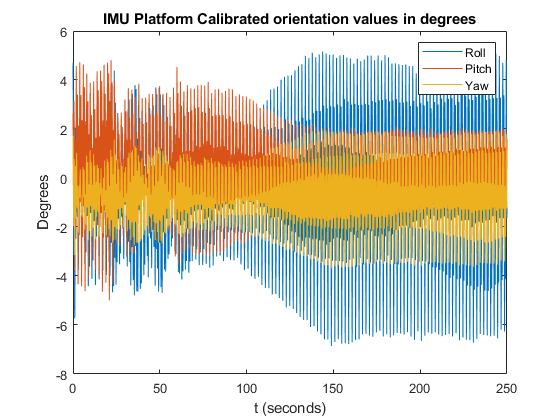


figure();
plot(t, rollCal, t, pitchCal, t, yawCal);
title('IMU Platform Calibrated orientation values in degrees')
legend("Roll", "Pitch", "Yaw")
xlabel('t (seconds)')
ylabel('Degrees')

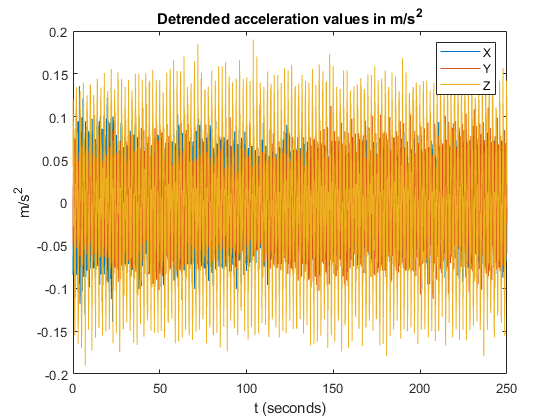



%Stage 2: Detrend IMU Time Series
%Detrend the IMU Time Series Values 

accX = embeddedDetrend(accXCal);
accY = embeddedDetrend(accYCal);
accZ = embeddedDetrend(accZCal);
roll = embeddedDetrend(rollCal);
pitch = embeddedDetrend(pitchCal);
yaw = embeddedDetrend(yawCal);

figure();
plot(t, accX, t, accY, t, accZ);
title('Detrended acceleration values in m/s^2')
legend("X", "Y", "Z")
xlabel('t (seconds)')
ylabel('m/s^2')

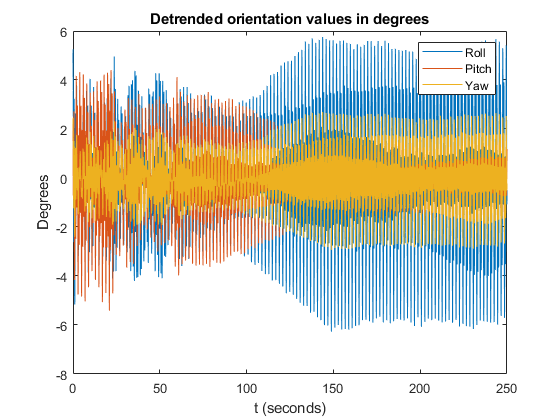


figure();
plot(t, roll, t, pitch, t, yaw);
title('Detrended orientation values in degrees')
legend("Roll", "Pitch", "Yaw")
xlabel('t (seconds)')
ylabel('Degrees')


%Stage 3: Correct to vertical
%Use detrended and calibrated IMU values to determine true vertical motion

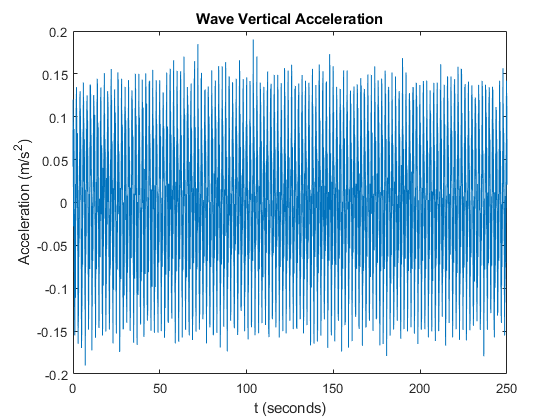

waveVertAcc = accZ; %vertCorrect(accX, accY, accZ, roll, pitch);

figure();
plot(t, waveVertAcc);
title('Wave Vertical Acceleration')
xlabel('t (seconds)')
ylabel('Acceleration (m/s^2)')

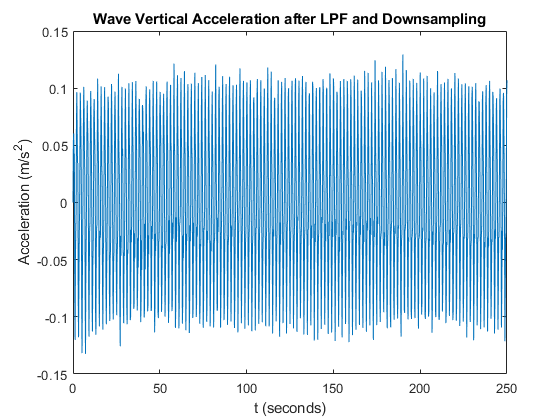


%Stage 4: LPF and decimation (prevents Harmonics in stage 5!) 
[t, waveVertAcc] = embeddedLowpass(t, waveVertAcc, d_sample_ratio);

figure();
plot(t, waveVertAcc);
title('Wave Vertical Acceleration after LPF and Downsampling')
xlabel('t (seconds)')
ylabel('Acceleration (m/s^2)')


%Stage 5: Frequency Transform
[f, waveAmplitudeFFTSingleSide, waveAmplitudeFFTDoubleSide] = embeddedFFT(waveVertAcc, Fs, N, d_sample_ratio);

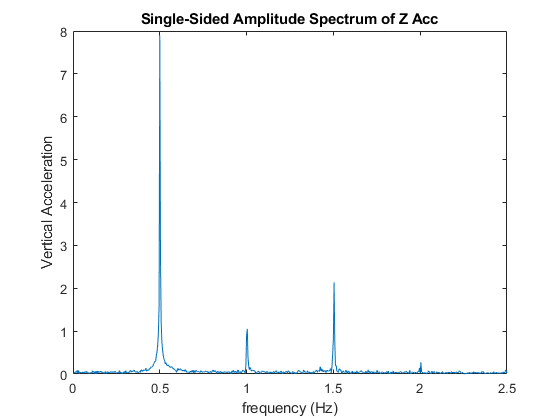


plot(f, waveAmplitudeFFTSingleSide) 
title('Single-Sided Amplitude Spectrum of Z Acc')
xlabel('frequency (Hz)')
ylabel('Vertical Acceleration')


%Stage 6
% Double integration and HPF
%%Wave Height Calculation
[t_trunc, waveAmplitude] = HPFDoubleIntegration(t, f, Fs, d_sample_ratio, waveAmplitudeFFTSingleSide, waveAmplitudeFFTDoubleSide);


plot(t_trunc, waveAmplitude)

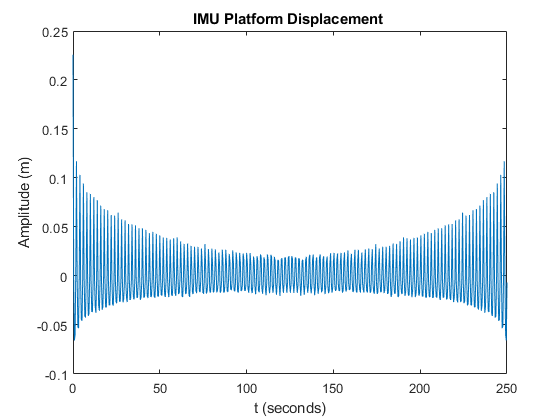

title('IMU Platform Displacement ')
xlabel('t (seconds)')
ylabel('Amplitude (m)')


%Window Time Series
pcosineWindow = tukeywin(length(waveAmplitude),0.75);

for i= 1:length(waveAmplitude)
    waveAmplitudeWindow(i) = waveAmplitude(i)*pcosineWindow(i);
end

plot(t_trunc, waveAmplitudeWindow)

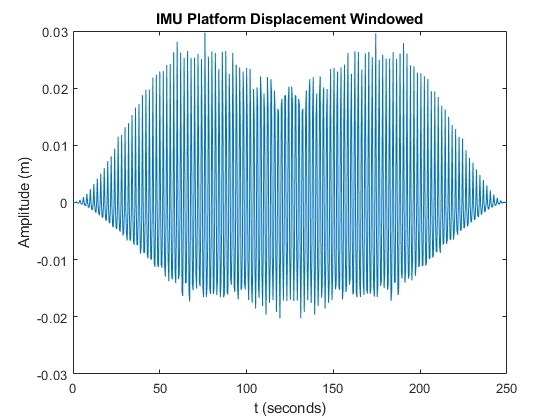

title('IMU Platform Displacement Windowed')
xlabel('t (seconds)')
ylabel('Amplitude (m)')


%Overlap Time Series 

%Stage 7: Segmentation and PSD 



%Stage 8: Extraction of key paramters